alpha=1+mod(269,3);

## Problem 1

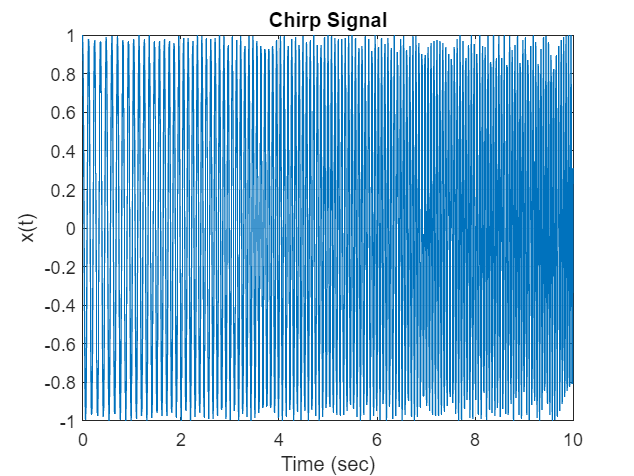

%Set the reference parameters
duration=10;
sampleRate=100;

%Define the frequency relation
A=2+2*alpha;
B=5+5*alpha;
time=0:1/sampleRate:duration-1/sampleRate;
f_t= 1.2*(time)+8;

%Generate the chirp signal
x_t= chirp(time, A, 10, B, "linear");
plot(time, x_t)
grid on;
title("Chirp Signal");
xlabel("Time (sec)");
ylabel("x(t)");

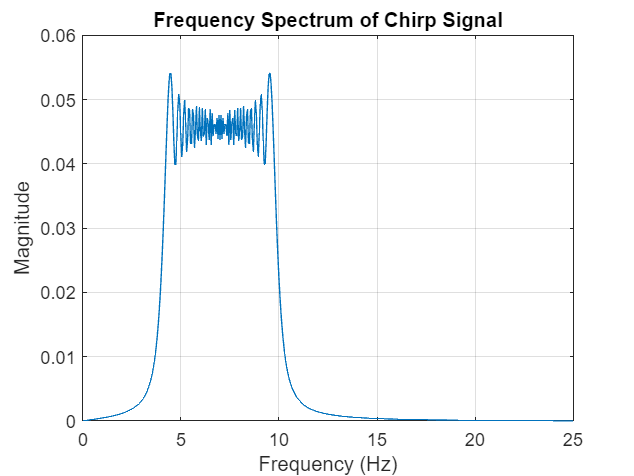


%Generate signal FFT and plot it
xt_dft=fft(x_t);
xt_mag=abs(xt_dft)/length(x_t);
xt_mag(1:length(xt_mag)/2+1);
fft_frequency=linspace(0,1,length(x_t)/2+1)*(sampleRate/4);
plot(fft_frequency, xt_mag(1:length(x_t)/2+1));
grid on;
title("Frequency Spectrum of Chirp Signal");
xlabel("Frequency (Hz)");
ylabel("Magnitude");

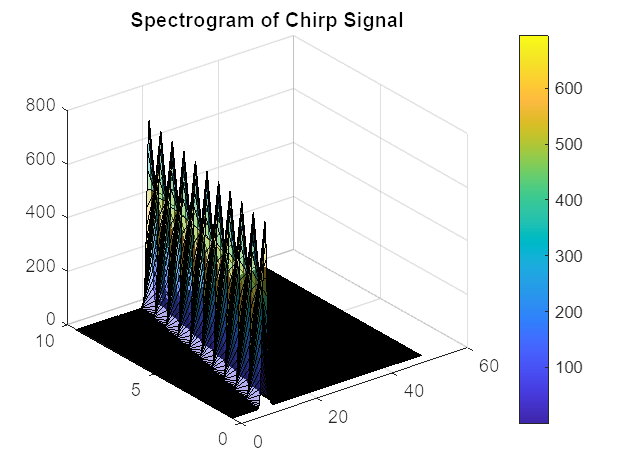


%Plot the spectrogram
[s,f,t]=spectrogram(x_t, hamming(100), 10, 2^nextpow2(length(x_t)), sampleRate);
surf(f,t,abs(s)'.^2,"FaceAlpha",0.4)
title("Spectrogram of Chirp Signal");
colorbar;

## Problem 2

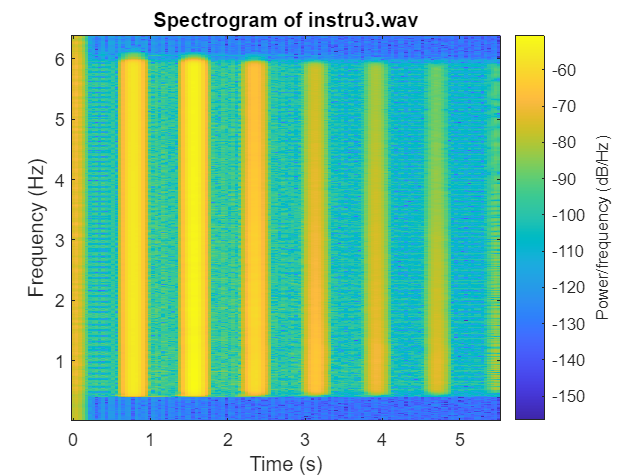

% Load the audio file
audioFile = 'instru3.wav';
[y, Fs] = audioread(audioFile);

% Define spectrogram parameters
windowSize = 100;
overlap = windowSize/10;
nfft = 2^nextpow2(windowSize);

% Compute the spectrogram
figure;
spectrogram(y, hamming(windowSize), overlap, [], Fs);
title('Spectrogram of instru3.wav');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

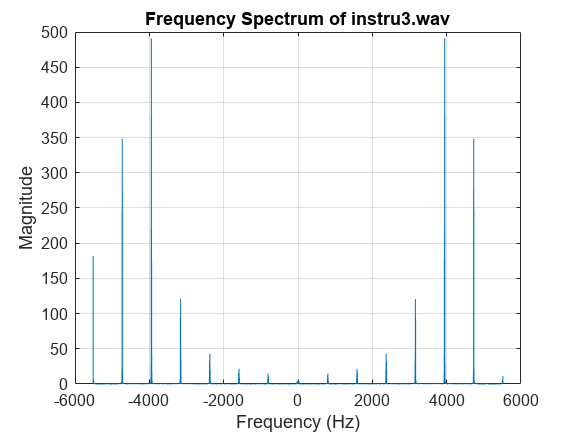


%Comput the DFT and Frequency
N = length(y);
dft_y = fft(y)/N;
magnitude=abs(dft_y)*N;
samplingRate=Fs/N;
frequencies = (-Fs/2):samplingRate:(Fs/2-samplingRate);

% Plot the magnitude spectrum
figure;
plot(frequencies, magnitude);
title('Frequency Spectrum of instru3.wav');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;


%Find the highest contribution to frequency spectrum
[max_magnitude, max_index] = max(magnitude);
fundamental_pitch = frequencies(max_index);

fprintf('Fundamental Pitch: %.2f Hz\n', abs(fundamental_pitch));

Fundamental Pitch: 3946.26 Hz


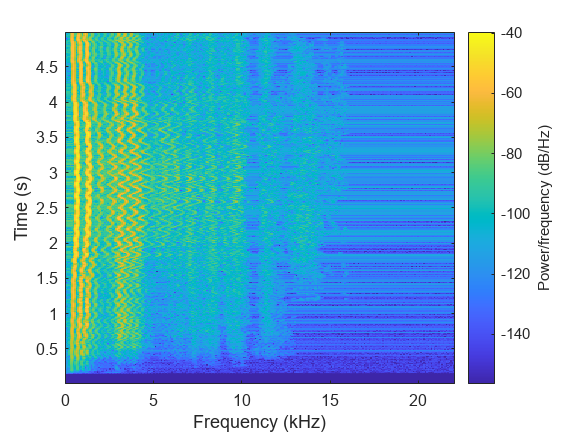

format long
% Load the audio file
[z, Fs] = audioread('Opera.wav');
N=length(z);

% Calculate the spectrogram
figure;
[s,f,t]=spectrogram(z, hamming(512), 256, [], Fs);
spectrogram(z, hamming(512), 256, [], Fs)

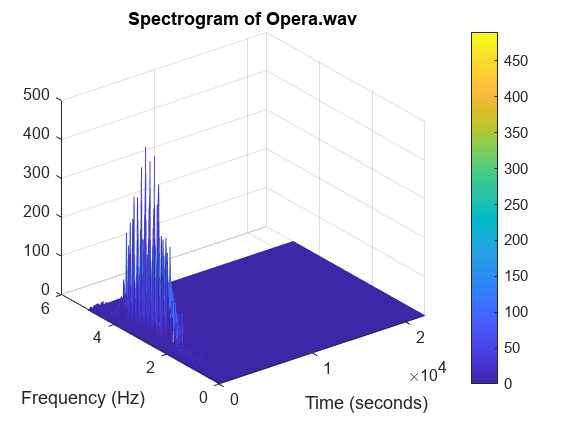

waterfall(f,t,abs(s)'.^2)
title('Spectrogram of Opera.wav');
xlabel('Time (seconds)');
ylabel('Frequency (Hz)');
colorbar;

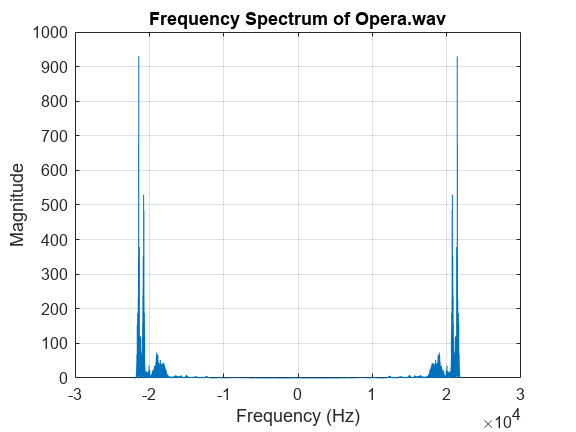


%Calculate DFT and Frequency
dft_z=fft(z)/N;
magnitude=abs(dft_z)*N;
samplingRate=Fs/N;
fs=(-Fs/2):samplingRate:(Fs/2-samplingRate);

%Plot the magnitude Spectrum
figure;
plot(fs, magnitude);
title('Frequency Spectrum of Opera.wav');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;


%Find the fundamental pitch
[~, index]=max(magnitude);
fundamental_frequencies=abs(fs(index))

fundamental_frequencies =      2.142720000000000e+04


## Problem 3

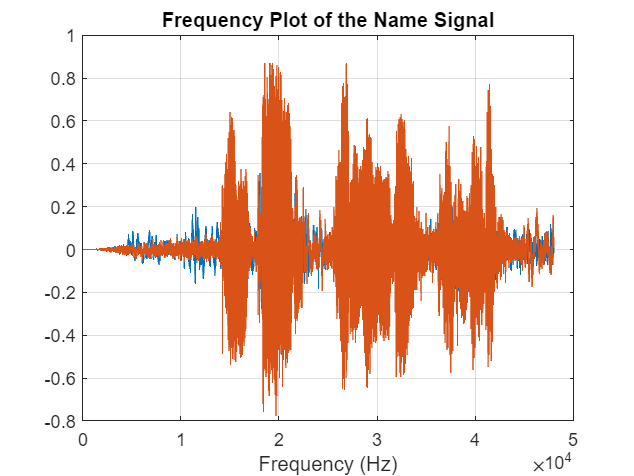

[N, Fs]=audioread("Name.wav.unknown");
complex_N=complex(N(:,1), N(:,2));
freqs=0:Fs/length(N):Fs-Fs/length(N);
N_mag=abs(complex_N);
plot(freqs, N);
title("Frequency Plot of the Name Signal");
xlabel("Frequency (Hz)")
grid on;

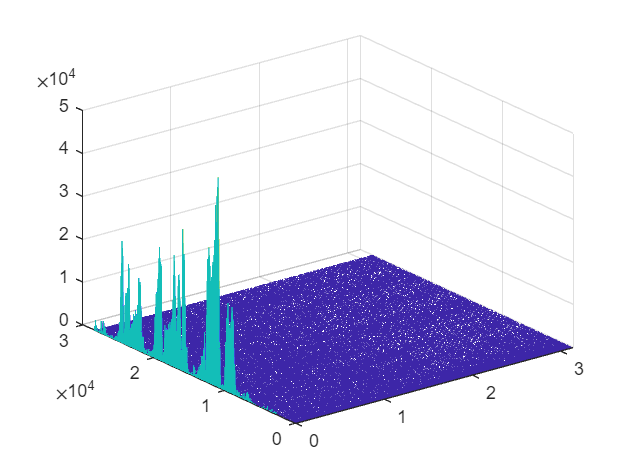

[s,f,t]=spectrogram(N_mag, hamming(1024), 512, 4000);
waterfall(f,t,abs(s)'.^2)

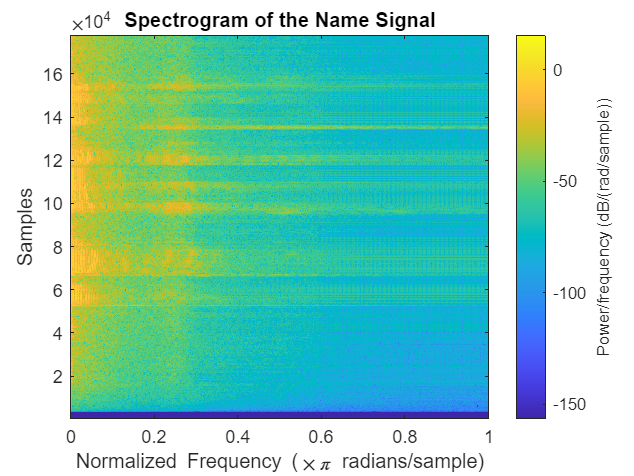

spectrogram(N_mag, hamming(1024), 512, 4000);
title("Spectrogram of the Name Signal");